Зададим параметры сигнала

clear all;
fs=8000;
mas=[15 6 19 21 25 32 7 30];%коды фонем в тестовом сигнале
% mas=12;
fft_size=512;
numcf=15;%количество MFCC коэффициентов
win_len=25.6e-3; %длинна одного кадра
%один код фонемы = одному кадру
t_length=round(win_len*fs); %количество отсчётов при данных fs и winlen
t=0:1/fs:(t_length-1)*1/fs;
f=[2093 293 659 1396 196];% массив частот (5 частот)

freq=[0 100 200 300 500 1000 1500 2000 3000 4000];
Am=[0.005 1 0.5 0.7 0.4 0.3 0.2 0.2 0.2 0.1];
mbFilt = designfilt('arbmagfir','FilterOrder',150, ...
         'Frequencies',freq,'Amplitudes',Am, ...
         'SampleRate',8000);
%fvtool(mbFilt); %смотрим АЧХ фильтра
fir_coefs=mbFilt.Coefficients;

Обучим GMM модель

gm=gmm_learning(f,fs,t,fft_size,numcf,fir_coefs);

Создадим сигнал через нелинейный элемент с кодом в mas

SP=GSS_generation(t,f,mas);
out_nl=nolinear_elmnt(SP);
SP = fftfilt(fir_coefs, out_nl);
input=frm2sig(SP);

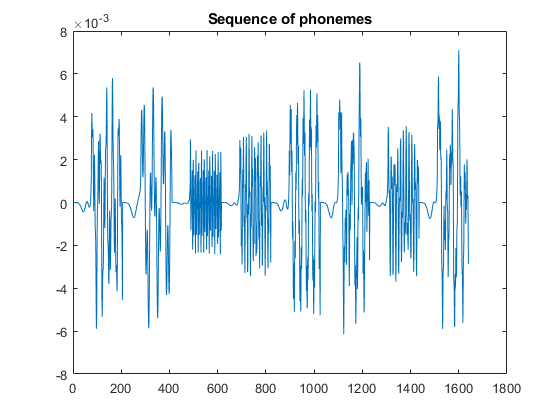


plot(input);
title("Sequence of phonemes")

Разделим сигнал на фреймы

frmwin=sig2frm(input,t_length);

count_frm = 8

signal_out=frmwin;

Найдём MFCC коэффициенты 

cf=mfcc_my(signal_out,fs,fft_size,numcf,0);

Кластеризуем коэффициенты

[idx,~,~] = cluster(gm,cf);
prb=appropriate(mas,idx)*100

prb = 100